# 第一周任务二 单节点储能分时电价套利

储能231 梁宏熙 学号206231315 额定功率2MW、能量容量2MWh；充放电效率0.90/0.95。 SoC在0.10至1.00内，初始与日末均为0.50；不计配电网潮流约束。 $SoC_t=SoC_{t-1}+(\eta_{ch}P_t^{ch}-P_t^{dis}/\eta_{dis})\Delta t/E$ $\max R=\sum_t c_t(P_t^{dis}-P_t^{ch})\Delta t$

clear;clc;close all;
work_dir=fileparts(mfilename('fullpath'));addpath(work_dir);
case_dir=week1_environment(work_dir);
Student=struct('Name','梁宏熙','Pinyin','lianghongxi','Class','储能231','ID',206231315);
Stu_ID=Student.ID;

## LP与MILP对比及功率容量试验

MILP以二进制u限制充放电互斥，调用MATLAB原生intlinprog； LP去掉互斥约束，调用MATLAB原生linprog。 核心建模、独立校验和输出位于配套week1_task12.m中。

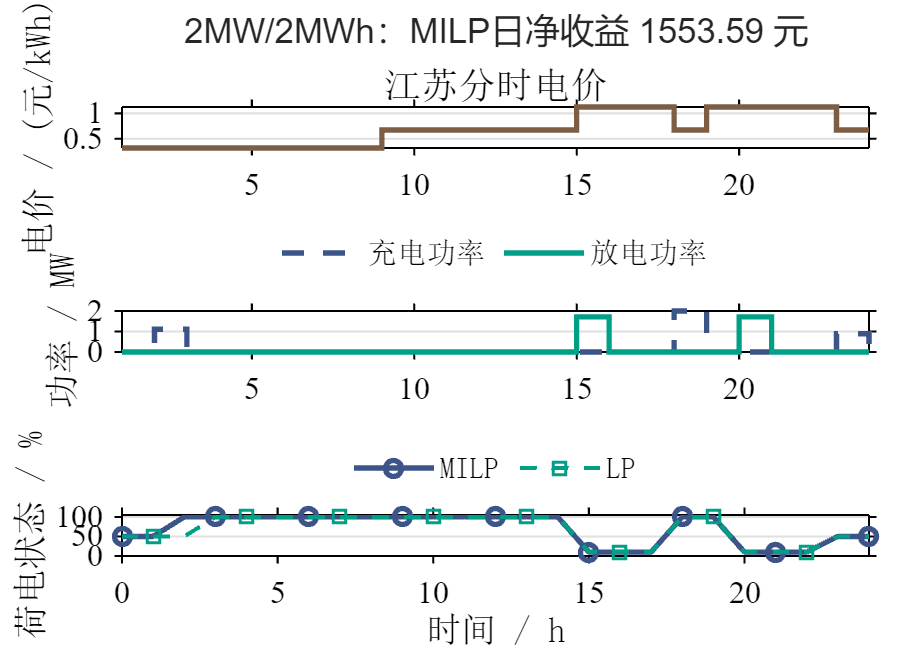

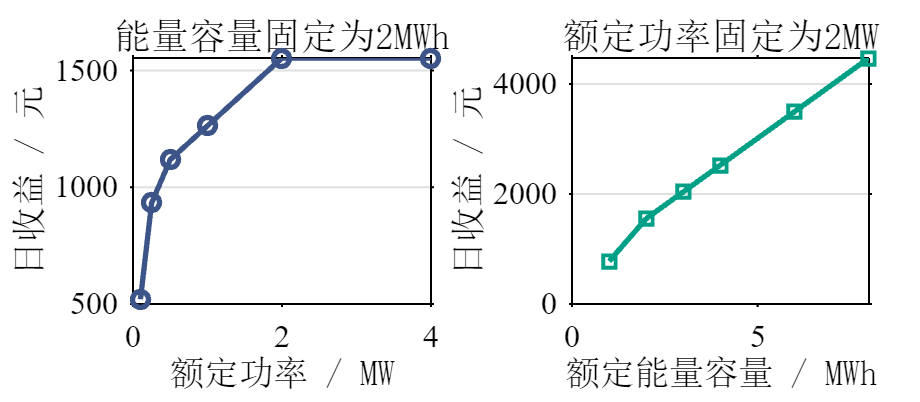

     Model          Solver        Power_MW    Energy_MWh    Revenue_Yuan    MaxSimultaneous_MW    EnergyResidual_MWh    TerminalSoCError    MinSoC    MaxSoC    PowerViolation_MW    IntegerError    Passed
    ________    ______________    ________    __________    ____________    __________________    __________________    ________________    ______    ______    _________________    ____________    ______

    {'LP'  }    {'linprog'   }       2            2            1553.6               0                 2.2204e-16               0             0.1        1               0                 0          true  
    {'MILP'}    {'intlinprog'}       2            2            1553.6               0                 2.2204e-16               0             0.1        1               0                 0          true  

    VariedParameter    Power_MW    Energy_MWh    Revenue_Yuan
    _______________    ________    __________    ____________

      {'Power' }          0.1          2            520.3

Task2=week1_task12(work_dir,Student,case_dir,2);

## 理论手算与结果解释

充入1MWh后可售电量为1*0.90*0.95=0.855MWh，往返损耗0.145MWh。 本课程电价恒正、往返效率小于1，且无网络约束，因此LP与MILP收益一致； 这不意味着网络调度模型也可以省略互斥约束。

disp(struct2table(Task2.Task2Comparison));

     Model          Solver        Power_MW    Energy_MWh    Revenue_Yuan    MaxSimultaneous_MW    EnergyResidual_MWh    TerminalSoCError    MinSoC    MaxSoC    PowerViolation_MW    IntegerError    Passed
    ________    ______________    ________    __________    ____________    __________________    __________________    ________________    ______    ______    _________________    ____________    ______

    {'LP'  }    {'linprog'   }       2            2            1553.6               0                 2.2204e-16               0             0.1        1               0                 0          true  
    {'MILP'}    {'intlinprog'}       2            2            1553.6               0                 2.2204e-16               0             0.1        1               0                 0          true  



disp(struct2table(Task2.Task2Sensitivity));

    VariedParameter    Power_MW    Energy_MWh    Revenue_Yuan
    _______________    ________    __________    ____________

      {'Power' }          0.1          2            520.39   
      {'Power' }         0.25          2            932.88   
      {'Power' }          0.5          2            1118.3   
      {'Power' }            1          2            1263.4   
      {'Power' }            2          2            1553.6   
      {'Power' }            4          2            1553.6   
      {'Energy'}            2          1             776.8   
      {'Energy'}            2          2            1553.6   
      {'Energy'}            2          3            2040.2   
      {'Energy'}            2          4            2526.8   
      {'Energy'}            2          6              3500   
      {'Energy'}            2          8            4473.2   



fprintf('任务二完成，1MWh输入可售出%.3fMWh。\n',Task2.SoldEnergyFrom1MWh);

任务二完成，1MWh输入可售出0.855MWh。
